## Create Image Datastore

clc;
clear; 

imageSize = [224 224];

imds = imageDatastore("Train\", "IncludeSubfolders",true, "LabelSource","foldernames");
[trainSet, ValSet, TestSet] = splitEachLabel(imds, 0.7, 0.15, 0.15)

trainSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_1.png';
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_10.png';
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_2.png'
                               ... and 2601 more
                              }
                     Folders: {
                              'C:\Users\ccesa\Desktop\DATI_new\Train'
                              }
                      Labels: [Adversarial; Adversarial; Adversarial ... and 2601 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: 

ValSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_50_fingerprint_4.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_50_fingerprint_5.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_50_fingerprint_6.png'
                               ... and 555 more
                              }
                     Folders: {
                              'C:\Users\ccesa\Desktop\DATI_new\Train'
                              }
                      Labels: [Adversarial; Adversarial; Adversarial ... and 555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

TestSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_7.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_8.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_9.png'
                               ... and 555 more
                              }
                     Folders: {
                              'C:\Users\ccesa\Desktop\DATI_new\Train'
                              }
                      Labels: [Adversarial; Adversarial; Adversarial ... and 555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                   


Train_aug = augmentedImageDatastore(imageSize,trainSet);
Val_aug = augmentedImageDatastore(imageSize,ValSet);
Test_aug = augmentedImageDatastore(imageSize,TestSet);

numClasses = numel(categories(trainSet.Labels));

## Network definition

net = resnet50;
%analyzeNetwork(net)
%net.Layers

lgraph = layerGraph(net);

fc = fullyConnectedLayer(2,"Name","new_fc")

fc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"fc1000",fc)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}



out = classificationLayer("Name","new_out")

out =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"ClassificationLayer_fc1000",out)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'new_out'}


## Training Option

batch_size = 16;
Max_epochs = 20;
ValidationFrequency = 16

IterForEpoch = 16


options = trainingOptions('adam', ...
    'Plots','training-progress',...
    "Verbose", true, ...
    "VerboseFrequency", 10,...
    "MaxEpochs", Max_epochs,...
    "MiniBatchSize", batch_size,...
    "Shuffle","every-epoch",...
    "ValidationData", Val_aug, ....
    "ValidationFrequency",ValidationFrequency,...
    "InitialLearnRate", 0.0005,...
    "LearnRateSchedule","piecewise", ...
    'LearnRateDropFactor',0.7, ...
    'LearnRateDropPeriod',3, ...
    "L2Regularization", 0.0001,...
    "ExecutionEnvironment","auto")

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 0.0050
             LearnRateSchedule: 'piecewise'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 5
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 8
                 MiniBatchSize: 32
                       Verbose: 1
              VerboseFrequency: 10
                ValidationData: [1×1 augmentedImageDatastore]
           ValidationFrequency: 16
            ValidationPatience: Inf
                       Shuffle: 'every-epoch'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
       

## Training Step

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:01:15 |       59.38% |       51.25% |       0.6663 |       1.0307 |          0.0005 |


|       1 |          10 |       00:02:58 |       68.75% |              |       0.6174 |              |          0.0005 |


|       1 |          16 |       00:04:58 |       62.50% |       60.39% |       0.7880 |       0.8454 |          0.0005 |


|       1 |          20 |       00:05:41 |       78.13% |              |       0.9465 |              |          0.0005 |


|       1 |          30 |       00:07:31 |       78.13% |              |       0.5310 |              |          0.0005 |


|       1 |          32 |       00:08:46 |       81.25% |       72.76% |       0.4219 |       0.6066 |          0.0005 |


|       1 |          40 |       00:10:14 |       90.63% |              |       0.2704 |              |          0.0005 |


|       1 |          48 |       00:12:40 |       87.50% |       77.24% |       0.3069 |       0.4986 |          0.0005 |


|       1 |          50 |       00:13:02 |       81.25% |              |       0.4370 |              |          0.0005 |


|       1 |          60 |       00:14:51 |       93.75% |              |       0.2072 |              |          0.0005 |


|       1 |          64 |       00:16:29 |       84.38% |       84.77% |       0.3706 |       0.3956 |          0.0005 |


|       1 |          70 |       00:17:34 |       96.88% |              |       0.0914 |              |          0.0005 |


|       1 |          80 |       00:20:24 |       90.63% |       88.53% |       0.1237 |       0.3299 |          0.0005 |


|       2 |          90 |       00:22:19 |       93.75% |              |       0.2175 |              |          0.0005 |


|       2 |          96 |       00:24:24 |      100.00% |       89.96% |       0.0233 |       0.2946 |          0.0005 |


|       2 |         100 |       00:25:11 |       96.88% |              |       0.1534 |              |          0.0005 |


|       2 |         110 |       00:27:04 |       93.75% |              |       0.0800 |              |          0.0005 |


|       2 |         112 |       00:28:24 |       96.88% |       82.80% |       0.0652 |       0.4259 |          0.0005 |


|       2 |         120 |       00:29:53 |      100.00% |              |       0.0350 |              |          0.0005 |


|       2 |         128 |       00:32:14 |      100.00% |       86.92% |       0.0164 |       0.3488 |          0.0005 |


|       2 |         130 |       00:32:36 |      100.00% |              |       0.0160 |              |          0.0005 |


|       2 |         140 |       00:34:25 |       93.75% |              |       0.0747 |              |          0.0005 |


|       2 |         144 |       00:36:03 |      100.00% |       88.71% |       0.0139 |       0.3147 |          0.0005 |


|       2 |         150 |       00:37:09 |      100.00% |              |       0.0360 |              |          0.0005 |


|       2 |         160 |       00:39:53 |      100.00% |       88.71% |       0.0092 |       0.3074 |          0.0005 |


|       3 |         170 |       00:41:45 |       96.88% |              |       0.0311 |              |          0.0005 |


|       3 |         176 |       00:43:52 |      100.00% |       90.32% |       0.0014 |       0.3135 |          0.0005 |


|       3 |         180 |       00:44:36 |      100.00% |              |       0.0049 |              |          0.0005 |


|       3 |         190 |       00:46:28 |      100.00% |              |       0.0019 |              |          0.0005 |


|       3 |         192 |       00:47:48 |      100.00% |       93.73% |       0.0009 |       0.1800 |          0.0005 |


|       3 |         200 |       00:49:18 |      100.00% |              |       0.0007 |              |          0.0005 |


|       3 |         208 |       00:51:47 |      100.00% |       90.50% |       0.0014 |       0.2462 |          0.0005 |


|       3 |         210 |       00:52:09 |      100.00% |              |       0.0037 |              |          0.0005 |


|       3 |         220 |       00:54:00 |      100.00% |              |       0.0065 |              |          0.0005 |


|       3 |         224 |       00:55:47 |      100.00% |       90.68% |       0.0025 |       0.2540 |          0.0005 |


|       3 |         230 |       00:56:55 |      100.00% |              |       0.0093 |              |          0.0005 |


|       3 |         240 |       00:59:48 |      100.00% |       93.55% |       0.0116 |       0.1722 |          0.0005 |


|       4 |         250 |       01:01:37 |      100.00% |              |       0.0069 |              |          0.0005 |


|       4 |         256 |       01:03:38 |      100.00% |       94.44% |       0.0110 |       0.1694 |          0.0005 |


|       4 |         260 |       01:04:23 |      100.00% |              |       0.0266 |              |          0.0005 |


|       4 |         270 |       01:06:17 |      100.00% |              |       0.0063 |              |          0.0005 |


|       4 |         272 |       01:07:35 |      100.00% |       94.27% |       0.0023 |       0.1700 |          0.0005 |


|       4 |         280 |       01:09:05 |      100.00% |              |       0.0001 |              |          0.0005 |


|       4 |         288 |       01:11:29 |      100.00% |       93.55% |       0.0011 |       0.2011 |          0.0005 |


|       4 |         290 |       01:11:51 |      100.00% |              |       0.0005 |              |          0.0005 |


|       4 |         300 |       01:13:43 |      100.00% |              |       0.0039 |              |          0.0005 |


|       4 |         304 |       01:15:25 |      100.00% |       91.40% |       0.0014 |       0.3340 |          0.0005 |


|       4 |         310 |       01:16:32 |      100.00% |              |       0.0012 |              |          0.0005 |


|       4 |         320 |       01:19:19 |      100.00% |       91.76% |       0.0026 |       0.2815 |          0.0005 |


|       5 |         330 |       01:21:10 |      100.00% |              |       0.0059 |              |          0.0005 |


|       5 |         336 |       01:23:16 |      100.00% |       95.16% |       0.0030 |       0.1637 |          0.0005 |


|       5 |         340 |       01:24:00 |      100.00% |              |       0.0079 |              |          0.0005 |


|       5 |         350 |       01:25:52 |      100.00% |              |       0.0062 |              |          0.0005 |


|       5 |         352 |       01:27:13 |      100.00% |       95.88% |       0.0335 |       0.1372 |          0.0005 |


|       5 |         360 |       01:28:42 |      100.00% |              |       0.0023 |              |          0.0005 |


|       5 |         368 |       01:31:08 |      100.00% |       94.62% |       0.0105 |       0.1460 |          0.0005 |


|       5 |         370 |       01:31:31 |      100.00% |              |       0.0007 |              |          0.0005 |


|       5 |         380 |       01:33:24 |      100.00% |              |       0.0073 |              |          0.0005 |


|       5 |         384 |       01:35:05 |      100.00% |       94.44% |       0.0002 |       0.1539 |          0.0005 |


|       5 |         390 |       01:36:12 |       96.88% |              |       0.0477 |              |          0.0005 |


|       5 |         400 |       01:39:01 |       96.88% |       93.37% |       0.0443 |       0.1673 |          0.0005 |


|       6 |         410 |       01:40:54 |       96.88% |              |       0.0253 |              |          0.0005 |


|       6 |         416 |       01:42:59 |      100.00% |       93.37% |       0.0012 |       0.2306 |          0.0005 |


|       6 |         420 |       01:43:51 |      100.00% |              |       0.0065 |              |          0.0005 |


|       6 |         430 |       01:45:46 |       96.88% |              |       0.1432 |              |          0.0005 |


|       6 |         432 |       01:47:03 |      100.00% |       92.29% |       0.0054 |       0.2794 |          0.0005 |


|       6 |         440 |       01:48:32 |      100.00% |              |       0.0054 |              |          0.0005 |


|       6 |         448 |       01:50:58 |      100.00% |       95.16% |       0.0014 |       0.1515 |          0.0005 |


|       6 |         450 |       01:51:20 |       96.88% |              |       0.0415 |              |          0.0005 |


|       6 |         460 |       01:53:17 |      100.00% |              |       0.0186 |              |          0.0005 |


|       6 |         464 |       01:54:59 |       96.88% |       92.47% |       0.0701 |       0.1749 |          0.0005 |


|       6 |         470 |       01:56:07 |       96.88% |              |       0.0988 |              |          0.0005 |


|       6 |         480 |       01:58:52 |      100.00% |       94.98% |       0.0066 |       0.2217 |          0.0005 |


|       7 |         490 |       02:00:41 |      100.00% |              |       0.0209 |              |          0.0005 |


|       7 |         496 |       02:02:41 |      100.00% |       92.83% |       0.0077 |       0.2799 |          0.0005 |


|       7 |         500 |       02:03:24 |      100.00% |              |       0.0093 |              |          0.0005 |


|       7 |         510 |       02:05:12 |      100.00% |              |       0.0004 |              |          0.0005 |


|       7 |         512 |       02:06:32 |      100.00% |       94.98% |       0.0080 |       0.1953 |          0.0005 |


|       7 |         520 |       02:07:58 |      100.00% |              |       0.0156 |              |          0.0005 |


|       7 |         528 |       02:10:19 |      100.00% |       91.04% |       0.0145 |       0.4262 |          0.0005 |


|       7 |         530 |       02:10:40 |      100.00% |              |       0.0024 |              |          0.0005 |


|       7 |         533 |       02:11:14 |       93.75% |              |       0.1587 |              |          0.0005 |
|======================================================================================================================|


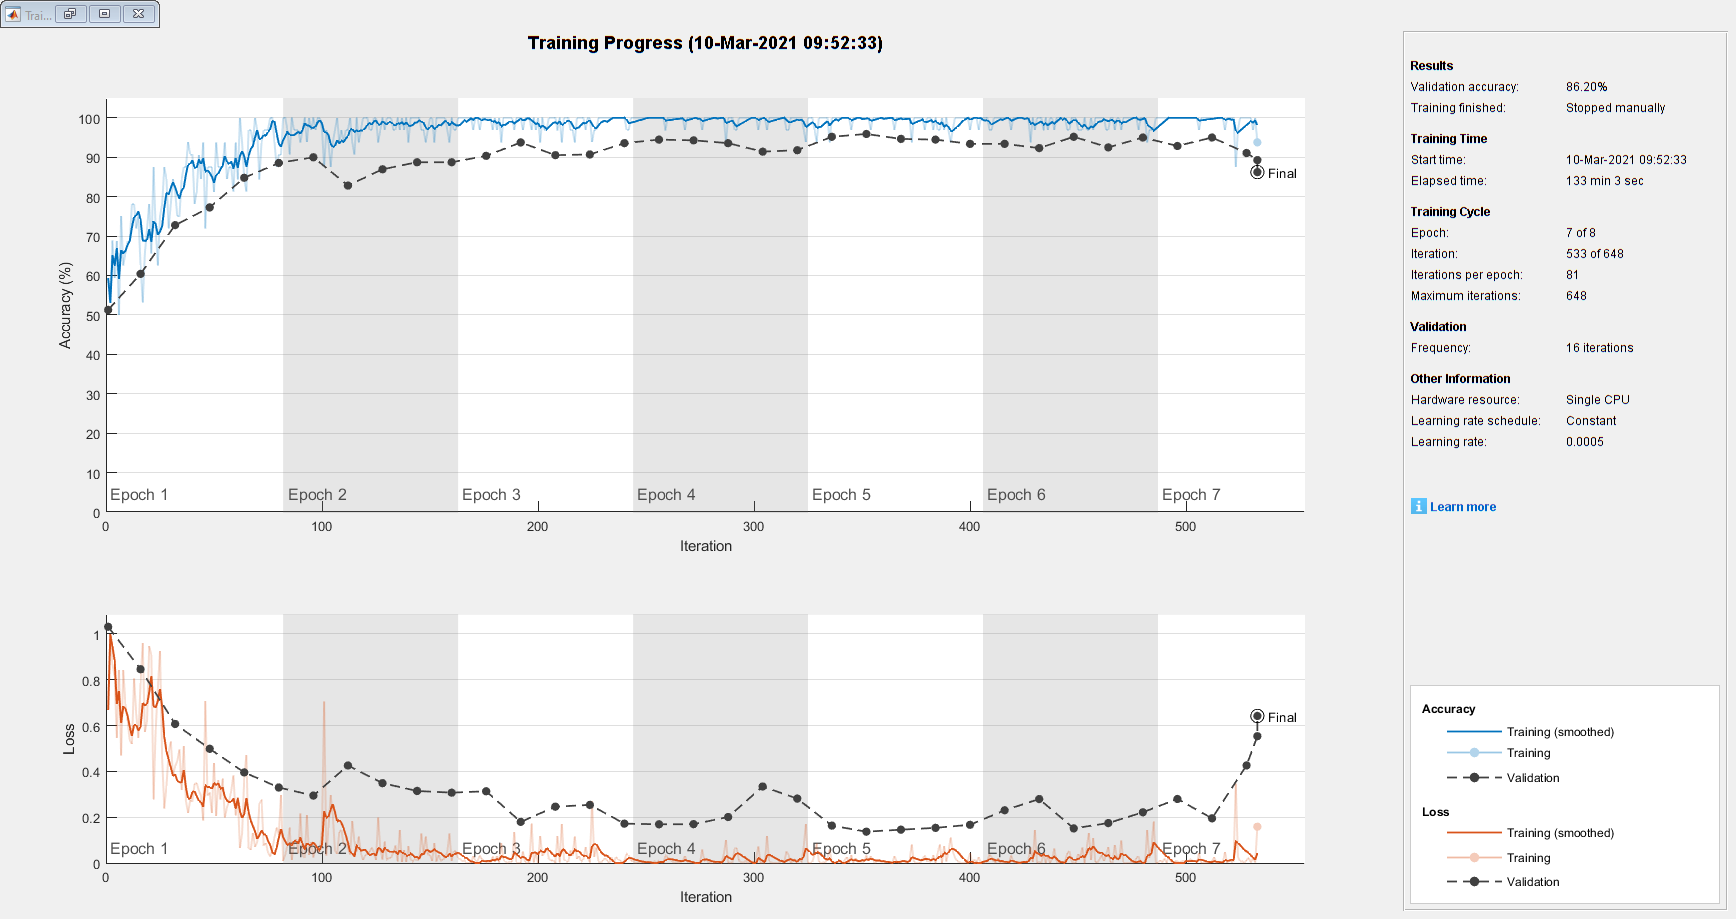

[net,info] = trainNetwork(Train_aug, lgraph, options);

## Prediction on Test

True_label = TestSet.Labels;
testpreds = classify(net,Test_aug);

## Performance

Accuracy = sum(True_label == testpreds)/numel(testpreds);
confusionchart(True_label, testpreds)
disp(Accuracy);

    0.8871




T = readtable('sampleSubmission.csv','Delimiter',',');
ids = T.Fingerprint;

preds_2 = {};
for i=1:numel(ids)
    imds = augmentedImageDatastore(imageSize,imageDatastore(['Test' filesep  ids{i}]));
    preds_2{end +1} = char(classify(net, imds)); 
end
submission = table(ids, preds_2', 'VariableNames', {'Fingerprint', 'Class'});
writetable(submission, 'SubmissionMatlab_NoAug.csv','Delimiter', ',');
